We first notice that $$\sum^{\infty}_{n=1}n^{-2} \to 2\dot\sqrt{n}$$

the most natural assuption would be that $$\sum^{\infty}_{n=1}n^{-a} \to \frac{n^{a}}{a}$$

but with numerical experiment, the conjecture is disproved.

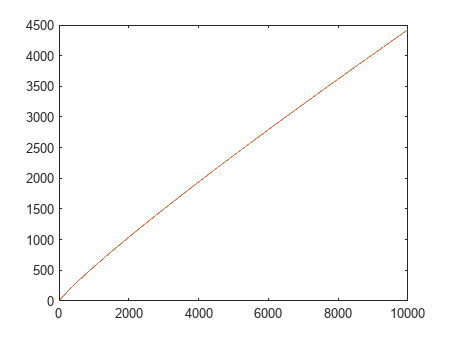

X = 1:1e4;
for n = 1:10
    clf
    a = 1/n;
    S = cumsum(X.^-a);
    plot(X,S)
    hold on 
    plot(X,X.^(1-a)/(1-a))
    drawnow
end

through further numerical experiment, we have figure out that the sum $\sum^{\infty}_{n=1}n^{-a} \to \frac{n^{1-a}}{1-a}$ matches with the result.

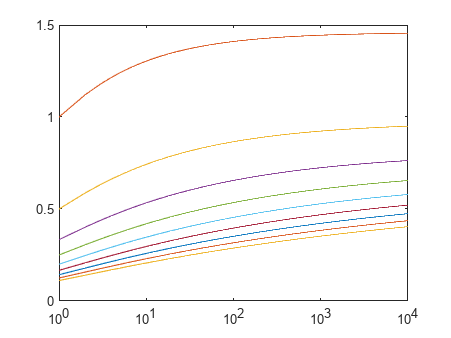

clf
for n = 1:10
    a = 1/n;
    S = cumsum(X.^-a);
    semilogx(X,X.^(1-a)/(1-a)-S)
    hold on
    drawnow
end

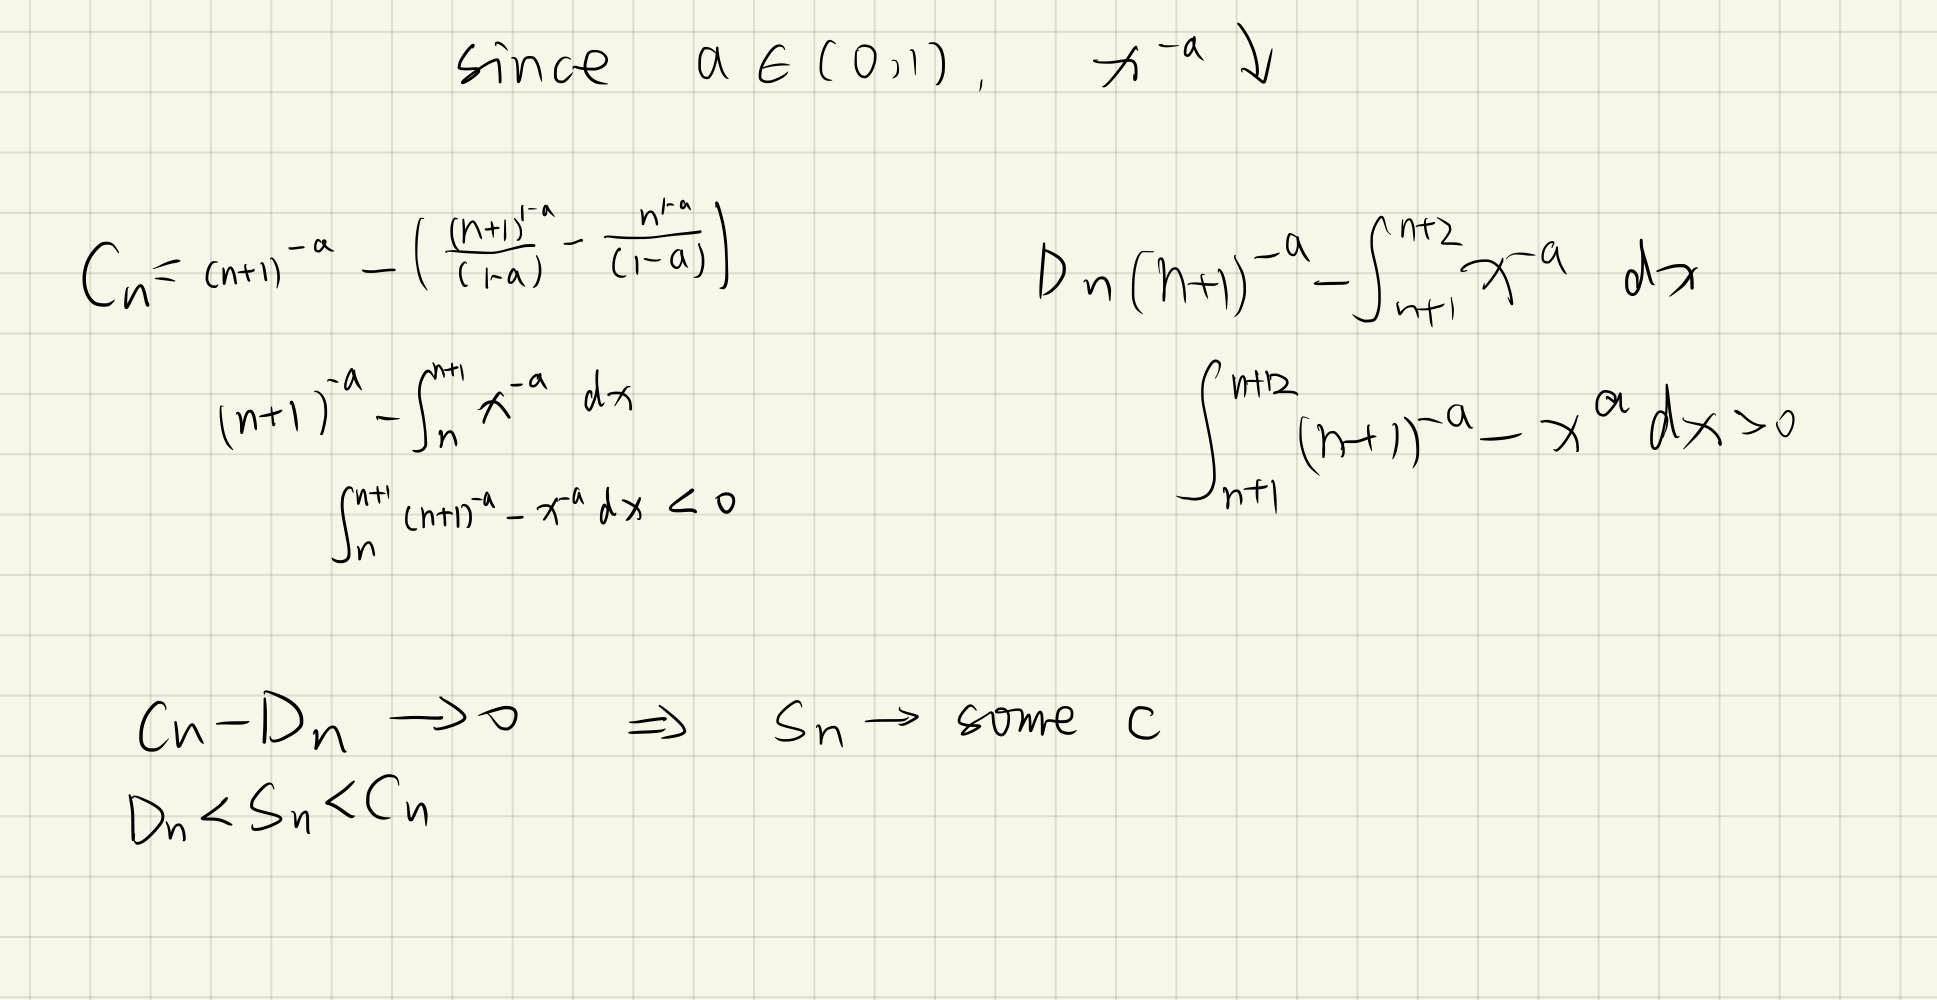

for a fine asymptotic estimation 

X = 1:1e7;
clf
a = 1/2;
S = cumsum(X.^-a);
N = logspace(1,7,7);
Err = zeros(7,1);
for k = 1:7
    Err(k) = X(k).^(1-a)/(1-a)-S(k);
end

ans = 6.3231e+03

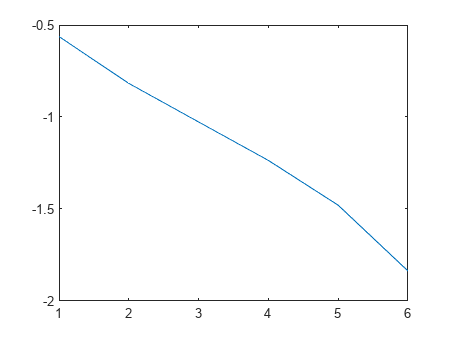

plot(1:6,log10(Err(end)-Err(1:end-1)))

Since this figure is linear, we know that $log f(n)=c_1^{log n}+c_2$

Apply an linear fit to the above figure:

p = polyfit(1:6,log10(Err(end)-Err(1:end-1)),1)

p =    -0.2447   -0.3034


we know c1 = -0.25, c2 = -0.3034.

problem 2

steps(5)

ans = 8

set n

n = 5;

list all possible conbination of 1 and 2 at the length of 5

Possibility = dec2bin(2^n-1:-1:0)-'0'+1;

kill all strings that goes larger then 5

Possibility(cumsum(Possibility,2)>5)=0;

romove duplicated strings

Possibility = unique(Possibility,'rows');

count number

sum(sum(Possibility,2)==5,"all")

ans = 8

same applys for n = 10

steps(10)

ans = 89

n = 10;
Possibility = dec2bin(2^n-1:-1:0)-'0'+1;
Possibility(cumsum(Possibility,2)>10)=0;
Possibility = unique(Possibility,'rows');
sum(sum(Possibility,2)==10,"all")

ans = 89

Notice that steps(n) = steps(n-1) + steps(n-2), and steps(1) = 1, steps(2) =  2;

it is the same as fabonacci, therefore steps(n) = fabonacci(n+1)

function k = steps(n)
    if n == 1
        k=1;
    elseif n == 2
        k=2;
    else
        k = steps(n-1)+steps(n-2);
    end
end